% Example Code: Loading Biosemi EEG Data
% Jerry Zhang
% December 2023

% 1. Extract multi-channel EEG data from Biosemi BDF files
% 2. Compute bandpass, bandstop and notch filtered EEG signals
% 3. Segment filtered EEG data
% 4. Compute FFT on EEG segments

## Load File and Extract Data

% Clear the environment and close all figures
close all;
clearvars;

% Set directory, get file info and load data
[filename, path] = uigetfile('.\*.bdf');
hdr = read_biosemi_bdf([path filename]);
EEG_raw = read_biosemi_bdf([path filename], hdr, hdr.nSamplesPre, hdr.nSamples)'; % This is from the 'Fieldtrip' toolbox
EEG_events = EEG_raw(2:end, end); % We don't need the event data for now
EEG_raw = EEG_raw(2:end, 1:end-1); % Discard the first garbage value

% Channels of interest
channels = {'A14', 'A15', 'A16', 'A17', 'A18'};
num_channels = length(channels);

% Initialize a matrix to store EEG data for each channel
EEG_filtered = zeros(size(EEG_raw, 1), num_channels);

## Filter EEG Data

% Filter settings
Fc_BP = [1 40];  % Bandpass filter from 1 to 40 Hz
Wn_BP = Fc_BP / (hdr.Fs / 2);  % Normalize frequency
[B_BP, A_BP] = butter(3, Wn_BP, 'bandpass');  % 6th order zero-phase Butterworth IIR

% Load and filter data for each specified channel
for i = 1:num_channels
    % Extract channel data
    channel_index = find(strcmp(hdr.label, channels{i}));
    channel_data = EEG_raw(:, channel_index);
    
    % Filter EEG data
    EEG_filtered(:, i) = filtfilt(B_BP, A_BP, channel_data);
end

% Now EEG_filtered contains the filtered data for each channel
% Each column in EEG_filtered corresponds to a channel in the 'channels' array


## Plot EEG Time-Series - Raw and Filtered

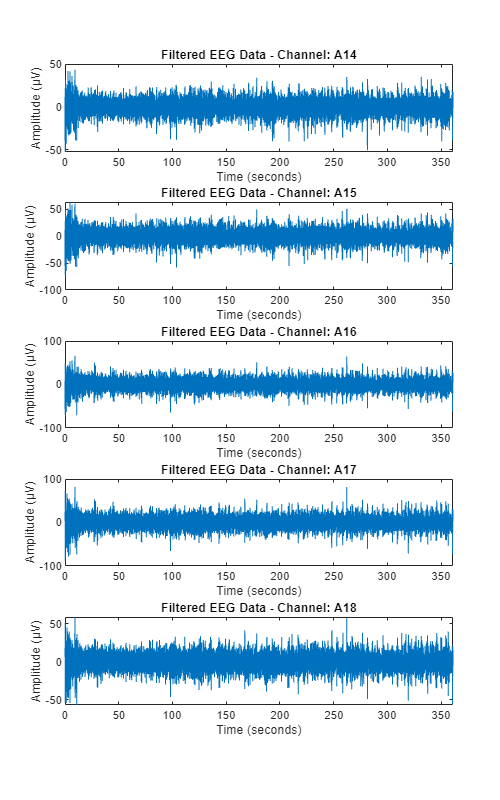

% Plotting the filtered data for each channel
figure;
for i = 1:num_channels
    subplot(num_channels, 1, i);
    plot((1:length(EEG_filtered(:, i))) / hdr.Fs, EEG_filtered(:, i));
    title(['Filtered EEG Data - Channel: ', channels{i}]);
    xlabel('Time (seconds)');
    ylabel('Amplitude (µV)');
    xlim([0 length(EEG_filtered(:, i)) / hdr.Fs]);  % Optional: adjust x-axis limits
end

% Adjust subplot spacing
set(gcf, 'Position', [100, 100, 500, 800]); % Adjust the figure size to see all plots clearly

## Segment EEG Data

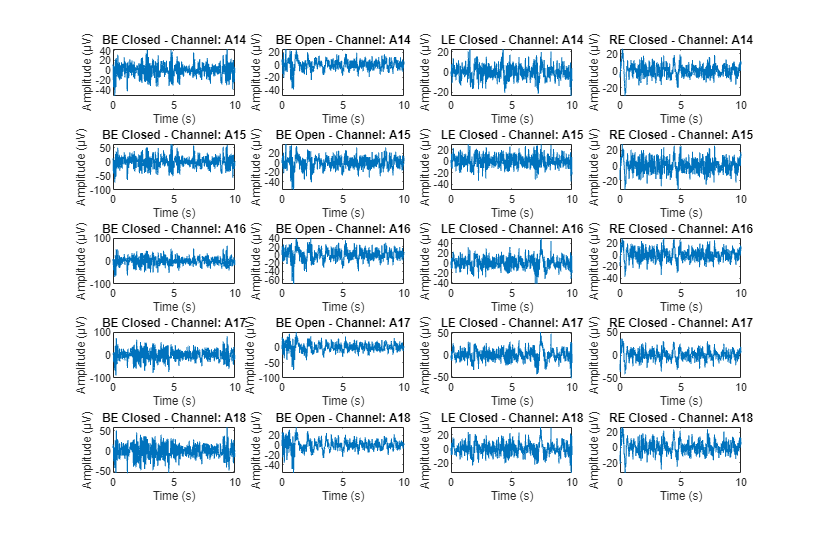

% Constants
sampling_rate = hdr.Fs;
segment_duration = 10; % Duration of each segment in seconds
samples_per_segment = segment_duration * sampling_rate;

% Initialize cell arrays to store segmented data
BE_Closed = cell(num_channels, 1);
BE_Open = cell(num_channels, 1);
LE_Closed = cell(num_channels, 1);
RE_Closed = cell(num_channels, 1);

% Segmenting data for each condition and each channel
for i = 1:num_channels
    % Both Eyes Closed (0-10 seconds)
    BE_Closed{i} = EEG_filtered(1:samples_per_segment, i);

    % Both Eyes Open (10-20 seconds)
    BE_Open{i} = EEG_filtered(samples_per_segment+1:2*samples_per_segment, i);

    % Left Eye Closed (20-30 seconds)
    LE_Closed{i} = EEG_filtered(2*samples_per_segment+1:3*samples_per_segment, i);

    % Right Eye Closed (30-40 seconds)
    RE_Closed{i} = EEG_filtered(3*samples_per_segment+1:4*samples_per_segment, i);
end

% Optionally, plotting segmented data for verification
figure;
for i = 1:num_channels
    subplot(num_channels, 4, (i-1)*4 + 1);
    plot((1:length(BE_Closed{i}))/sampling_rate, BE_Closed{i});
    title(['BE Closed - Channel: ', channels{i}]);
    xlabel('Time (s)');
    ylabel('Amplitude (µV)');

    subplot(num_channels, 4, (i-1)*4 + 2);
    plot((1:length(BE_Open{i}))/sampling_rate, BE_Open{i});
    title(['BE Open - Channel: ', channels{i}]);
    xlabel('Time (s)');
    ylabel('Amplitude (µV)');

    subplot(num_channels, 4, (i-1)*4 + 3);
    plot((1:length(LE_Closed{i}))/sampling_rate, LE_Closed{i});
    title(['LE Closed - Channel: ', channels{i}]);
    xlabel('Time (s)');
    ylabel('Amplitude (µV)');

    subplot(num_channels, 4, (i-1)*4 + 4);
    plot((1:length(RE_Closed{i}))/sampling_rate, RE_Closed{i});
    title(['RE Closed - Channel: ', channels{i}]);
    xlabel('Time (s)');
    ylabel('Amplitude (µV)');
end

% Adjust figure size to display all subplots clearly
set(gcf, 'Position', [100, 100, 1200, 800]); % Make the figure large enough to see details

## Plot and Compare EEG Fourier Spectrums

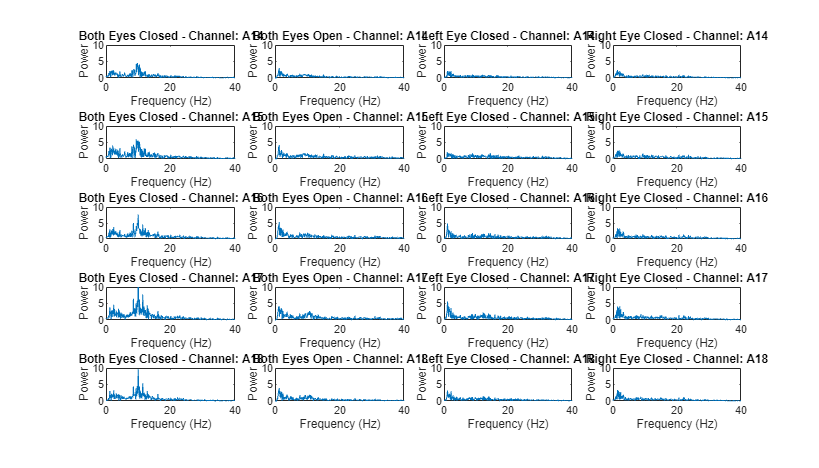

% Constants for FFT
N = samples_per_segment; % Number of points in FFT (same as samples per segment)

% Initialize arrays to store the frequency vector and power spectra
frequencies = hdr.Fs * (0:(N/2))/N; % Frequency vector
power_spectra = struct('BE_Closed', [], 'BE_Open', [], 'LE_Closed', [], 'RE_Closed', []);

% Process each channel and condition
for i = 1:num_channels
    % FFT and Power Spectrum for Each Condition
    % Both Eyes Closed
    fft_data = fft(BE_Closed{i}, N);
    P2 = abs(fft_data/N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    power_spectra.BE_Closed(:, i) = P1;

    % Both Eyes Open
    fft_data = fft(BE_Open{i}, N);
    P2 = abs(fft_data/N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    power_spectra.BE_Open(:, i) = P1;

    % Left Eye Closed
    fft_data = fft(LE_Closed{i}, N);
    P2 = abs(fft_data/N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    power_spectra.LE_Closed(:, i) = P1;

    % Right Eye Closed
    fft_data = fft(RE_Closed{i}, N);
    P2 = abs(fft_data/N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    power_spectra.RE_Closed(:, i) = P1;
end

% Plotting the power spectra for each condition and channel
figure;
plot_titles = {'Both Eyes Closed', 'Both Eyes Open', 'Left Eye Closed', 'Right Eye Closed'};
conditions = fieldnames(power_spectra);
for j = 1:length(conditions)
    for i = 1:num_channels
        subplot(num_channels, length(conditions), (i-1) * length(conditions) + j);
        plot(frequencies, power_spectra.(conditions{j})(:, i));
        title([plot_titles{j}, ' - Channel: ', channels{i}]);
        xlabel('Frequency (Hz)');
        ylabel('Power');
        xlim([0 40]); % Focus on the typical EEG frequency range
        ylim([0 10]);
    end
end

% Adjust figure size to display all subplots clearly
set(gcf, 'Position', [100, 100, 1400, 800]); % Make the figure large enough to see details

## Average Power Spectrum

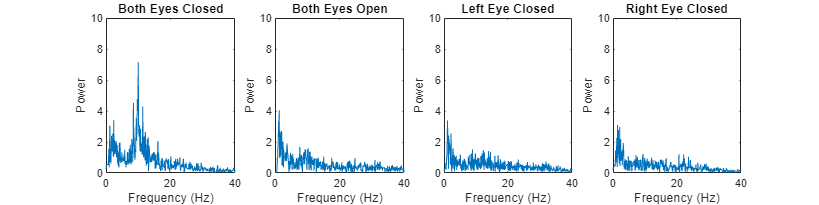

% Constants for FFT
N = samples_per_segment; % Number of points in FFT (same as samples per segment)

% Frequency vector
frequencies = hdr.Fs * (0:(N/2))/N;

% Initialize matrices to store averaged EEG data for each condition
avg_BE_Closed = mean(cell2mat(BE_Closed'), 2);
avg_BE_Open = mean(cell2mat(BE_Open'), 2);
avg_LE_Closed = mean(cell2mat(LE_Closed'), 2);
avg_RE_Closed = mean(cell2mat(RE_Closed'), 2);

% Initialize structure to store power spectra
avg_power_spectra = struct('BE_Closed', [], 'BE_Open', [], 'LE_Closed', [], 'RE_Closed', []);

% Calculate FFT and Power Spectrum for Averaged Data for each condition
condition_names = {'BE_Closed', 'BE_Open', 'LE_Closed', 'RE_Closed'};
for idx = 1:length(condition_names)
    condition_data = eval(['avg_' condition_names{idx}]);  % Retrieve the average data for the condition

    % FFT of the averaged data
    fft_data = fft(condition_data, N);
    P2 = abs(fft_data / N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);  % Single-sided spectrum

    % Store the power spectrum
    avg_power_spectra.(condition_names{idx}) = P1;
end

% Plotting the averaged power spectra for each condition
figure;
plot_titles = {'Both Eyes Closed', 'Both Eyes Open', 'Left Eye Closed', 'Right Eye Closed'};
for j = 1:length(plot_titles)
    subplot(1, length(plot_titles), j);
    plot(frequencies, avg_power_spectra.(condition_names{j}));
    title(plot_titles{j});
    xlabel('Frequency (Hz)');
    ylabel('Power');
    xlim([0 40]); % Focus on the typical EEG frequency range
    ylim([0 10]);
end

% Adjust figure size to display all subplots clearly
set(gcf, 'Position', [100, 100, 1200, 300]); % Adjust width and height for clarity

## Power, Frequency and Reactivity

% Find indices for the frequency range 8-12 Hz
freq_range = frequencies >= 8 & frequencies <= 12;
freq_range_indices = find(freq_range);

% Find the maximum power and corresponding frequency within 8-12 Hz range
[max_BE_Closed, idx_closed] = max(avg_power_spectra.BE_Closed(freq_range_indices));
max_freq_closed = frequencies(freq_range_indices(idx_closed));

[max_BE_Open, idx_open] = max(avg_power_spectra.BE_Open(freq_range_indices));
max_freq_open = frequencies(freq_range_indices(idx_open));

% Reactivity calculation (Closed - Open)
reactivity = max_BE_Closed - max_BE_Open;

% Display the results
fprintf('Maximum Power in BE_Closed (8-12 Hz): %f at %f Hz\n', max_BE_Closed, max_freq_closed);

Maximum Power in BE_Closed (8-12 Hz): 7.145875 at 10.000000 Hz


fprintf('Maximum Power in BE_Open (8-12 Hz): %f at %f Hz\n', max_BE_Open, max_freq_open);

Maximum Power in BE_Open (8-12 Hz): 1.592433 at 10.300000 Hz


fprintf('Reactivity (Closed - Open): %f\n', reactivity);

Reactivity (Closed - Open): 5.553442


## Bandwidth

% Constants for dB calculation
dB_drop = 3;

% Calculate the power in dB for the Closed condition within the alpha range
power_BE_Closed_dB = 10 * log10(avg_power_spectra.BE_Closed(freq_range_indices));

% Get the dB value 3 dB below the maximum power for the Closed condition
target_dB_closed = max(power_BE_Closed_dB) - dB_drop;

% Find the frequencies at -3dB points for Both Eyes Closed
left_idx_closed = find(power_BE_Closed_dB(1:idx_closed) <= target_dB_closed, 1, 'last');
right_idx_closed = find(power_BE_Closed_dB(idx_closed:end) <= target_dB_closed, 1, 'first') + idx_closed - 1;

left_freq_closed = frequencies(freq_range_indices(left_idx_closed));
right_freq_closed = frequencies(freq_range_indices(right_idx_closed));

% Calculate bandwidth for the Closed condition
bandwidth_closed = right_freq_closed - left_freq_closed;

% Display the result
fprintf('Bandwidth for BE_Closed around %f Hz: %f Hz (%f Hz to %f Hz)\n', max_freq_closed, bandwidth_closed, left_freq_closed, right_freq_closed);

Bandwidth for BE_Closed around 10.000000 Hz: 0.500000 Hz (9.600000 Hz to 10.100000 Hz)


## Coherence Peak

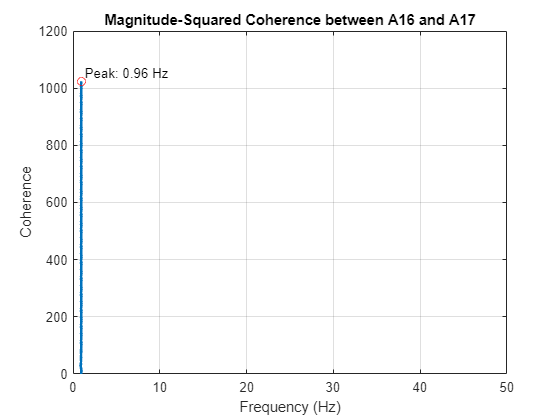

A16_data = BE_Closed{4};  % Assuming channel A16 is the fourth in the list
A17_data = BE_Closed{5};  % Assuming channel A17 is the fifth in the list

% Constants
Fs = hdr.Fs;  % Sampling frequency
window = hamming(256);  % Window for coherence estimation
noverlap = 128;  % Number of overlapping samples per segment
nfft = 512;  % Number of FFT points

% Calculate Coherence
[f, Cxy] = mscohere(A16_data, A17_data, window, noverlap, nfft, Fs);

% Find the peak coherence and its frequency
[peakCoherence, idx] = max(Cxy);
peakFrequency = f(idx);

% Plot Coherence
figure;
plot(f, Cxy, 'LineWidth', 2);
title('Magnitude-Squared Coherence between A16 and A17');
xlabel('Frequency (Hz)');
ylabel('Coherence');
grid on;
xlim([0 50]);  % Limit frequency for better visibility
hold on;
plot(peakFrequency, peakCoherence, 'ro');  % Mark the peak
text(peakFrequency, peakCoherence, sprintf(' Peak: %.2f Hz', peakFrequency), 'VerticalAlignment', 'bottom');


% Display the peak coherence value and frequency
fprintf('Peak Coherence: %f at %f Hz\n', peakCoherence, peakFrequency);

Peak Coherence: 1024.000000 at 0.959209 Hz
